# Quantum Information Science HW P1

Harris A. Ransom

10/09/2024

### Question 1

H = [0 0 0 1 1 1 1
     0 1 1 0 0 1 1
     1 0 1 0 1 0 1];
HT = H'

HT =      0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1


zeroVec = [0, 0, 0];
c = [];
% Goal: Find c*HT = B
for i = 0:(2^7 - 1) 
    ci = dec2bin(i, 7)-'0';
    b = [];
    for j = 1:3
        bi = mod(dot(ci, HT(:,j)), 2);
        b(end+1) = bi;
    end
    if (all(zeroVec == b))
        c = cat(1, c, ci);
    end
end
c

c =      0     0     0     0     0     0     0
     0     0     0     1     1     1     1
     0     0     1     0     1     1     0
     0     0     1     1     0     0     1
     0     1     0     0     1     0     1
     0     1     0     1     0     1     0
     0     1     1     0     0     1     1
     0     1     1     1     1     0     0
     1     0     0     0     0     1     1
     1     0     0     1     1     0     0


### Question 2

[rows, cols] = size(c);

% Get the Hamming weights for each of the codewords
hWeights = zeros(1, rows);
for i = 1:rows
    for j = 1:cols
        if (c(i,j) == 1)
            hWeights(i) = hWeights(i) + 1;
        end
    end
end
normalizedHammingWeights = hWeights ./ (rows);
hWeights

hWeights =      0     4     3     3     3     3     4     4     3     3     4     4     4     4     3     7


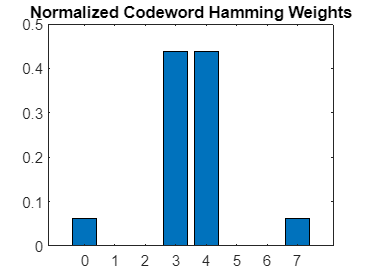


% Get counts for each of the possible hamming weights
counts = zeros(1, 7);
for i=0:max(hWeights)
    counts(i+1) = sum(hWeights == i);
end
countFreqs = counts ./ rows;

%histogram(normalizedHammingWeights);
bar(0:max(hWeights), countFreqs)
title("Normalized Codeword Hamming Weights");

### Question 3

% Get Hamming distances
normHDist = squareform(pdist(c, 'hamming'));
hDist = cols .* normHDist

hDist =      0     4     3     3     3     3     4     4     3     3     4     4     4     4     3     7
     4     0     3     3     3     3     4     4     3     3     4     4     4     4     7     3
     3     3     0     4     4     4     3     3     4     4     3     3     3     7     4     4
     3     3     4     0     4     4     3     3     4     4     3     3     7     3     4     4
     3     3     4     4     0     4     3     3     4     4     3     7     3     3     4     4
     3     3     4     4     4     0     3     3     4     4     7     3     3     3     4     4
     4     4     3     3     3     3     0     4     3     7     4     4     4     4     3     3
     4     4     3     3     3     3     4     0     7     3     4     4     4     4     3     3
     3     3     4     4     4     4     3     7     0     4     3     3     3     3     4     4
     3     3     4     4     4     4     7     3     4     0     3     3     3     3     4     4


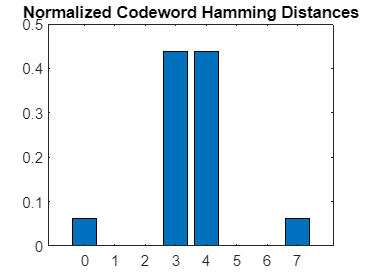


% Get counts
hDistVec = reshape(hDist.',1,[]);
counts = zeros(1, 7);
for i=0:max(hDistVec)
    counts(i+1) = sum(hDistVec == i);
end
countFreqs = counts ./ (rows^2);

% Plot distribution
%surf(hDist)
%histogram(normHDist);
bar(0:max(hDistVec), countFreqs)
title("Normalized Codeword Hamming Distances");

### Question 4

% Chosen nonzero codeword - 4
% 0, 0, 1, 1, 0, 0, 1
distances = [];
for i = 1:length(hDist)
    distances(end+1) = hDist(4, i);
end
normDistances = distances ./ cols;
distances

distances =      3     3     4     0     4     4     3     3     4     4     3     3     7     3     4     4



% Get counts
counts = zeros(1, 7);
for i=0:max(distances)
    counts(i+1) = sum(distances == i);
end
countFreqs = counts ./ (rows)

countFreqs =     0.0625         0         0    0.4375    0.4375         0         0    0.0625


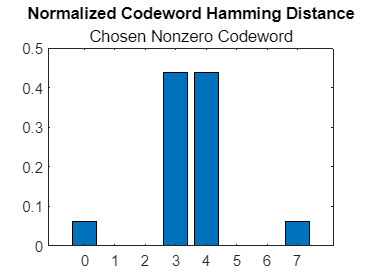


%histogram(normDistances, 'NumBins', 4);
bar(0:max(distances), countFreqs)
title("Normalized Codeword Hamming Distance")
subtitle("Chosen Nonzero Codeword")